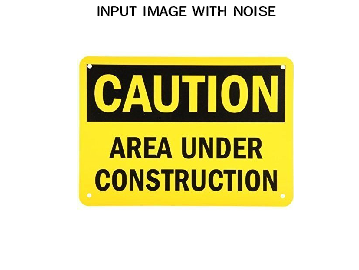

clc
Inputimage=imread("/MATLAB Drive/caution.jpg");
figure(1)
imshow(Inputimage);
title('INPUT IMAGE WITH NOISE')

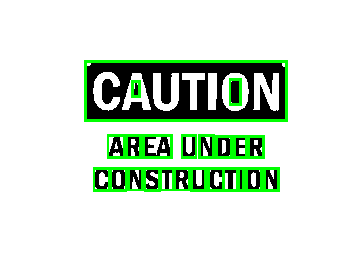

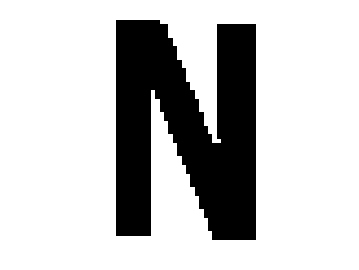


%% Convert to gray scale
if size(Inputimage,3)==3 % RGB image
Inputimage=rgb2gray(Inputimage);
end

%% Convert to binary image
threshold = graythresh(Inputimage);
Inputimage =~im2bw(Inputimage,threshold);


%% Remove all object containing fewer than 30 pixels
Inputimage = bwareaopen(Inputimage,30);
pause(1);


%% Label connected components
[L Ne]=bwlabel(Inputimage);
propied=regionprops(L,'BoundingBox');
imshow(~Inputimage);
hold on
for n=1:size(propied,1)
rectangle('Position',propied(n).BoundingBox,'EdgeColor','g','LineWidth',2)
end
hold off
pause (1);


%% Objects extraction
figure
for n=1:Ne
[r,c] = find(L==n);
n1=Inputimage(min(r):max(r),min(c):max(c));
imshow(~n1);
pause(0.5)
end